### Underwater Image

clear
clc

% import Bc & Dc
% load("mat data\Colorchecker_Dc_linear_RGBValue_NEW.mat")
load("mat data\Colorchecker03_Dc_linear_RGBValue_BLACK.mat")
load("mat data\Colorchecker02_Backscatter_RGB_linear_1m5m_BLACK.mat");


for k = 1:24 %color checker
    Ic_R_linear(:,:,:,k) = Dc_R_linear(:,:,:,k) + BackScatter_R_linear;
    Ic_G_linear(:,:,:,k) = Dc_G_linear(:,:,:,k) + BackScatter_G_linear;
    Ic_B_linear(:,:,:,k) = Dc_B_linear(:,:,:,k) + BackScatter_B_linear;

end


from linear sRG to sRGB

Ic_R = lin2rgb(Ic_R_linear);
Ic_G = lin2rgb(Ic_G_linear);
Ic_B = lin2rgb(Ic_B_linear);

#### save restoraated value to mat. 

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\mat data\';
save(strcat(fpath, "Colorchecker04_Ic_linear_RGBValue_BLACK.mat"),"Ic_R_linear","Ic_G_linear","Ic_B_linear")

PLOT

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\資料整理\Ic_image\';
typename = {'JerlovI','JerlovIA','JerlovIB','JerlovII','JerlovIII','Jerlov1C','Jerlov3C','Jerlov5C'};
d = [1 5];
z = [1:10];
for i = 1:numel(typename) % jerlov 8 types
    for j = 1:numel(d) %水深 2 depth
        for k = 1:10 %物距
        plotcolorpatch(Ic_R(k,i,j,:),Ic_G(k,i,j,:),Ic_B(k,i,j,:));
        title(strcat(typename{i}," at depth ",num2str(d(j)),'m, at distance ',num2str(z(k)),' m'))
%         set(gcf,"Visible","on")
        saveas(gcf,strcat(fpath,'Ic_',typename{i},"_depth",num2str(d(j)),'m_distance',num2str(z(k)),'m'),'bmp')
        end
    end
end
 

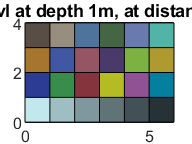

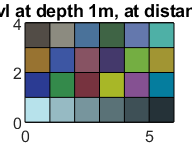

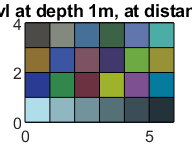

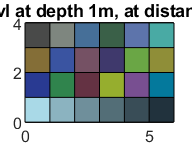

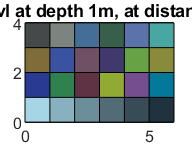

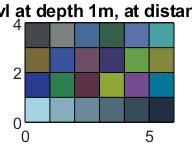

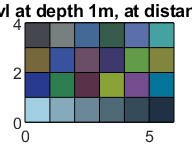

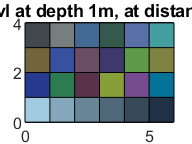

function plotcolorpatch(R,G,B)
Nr_R = reshape(R, 4, 6);

Nr_G = reshape(G, 4, 6);
Nr_B = reshape(B, 4, 6);
%%
x = 0 : 6;
y = 0 : 4;
%% 網格xy首末
x1 = [x(1) x(end)]';
y1 = [y(1) y(end)]';

%% 網格所有線的xData
x2 = repmat(x1, 1, length(y)-2);

x3 = repmat(x(2):x(end-1), 2, 1);

xData = [x2 x3];

%% 網格所有線的yData
y2 = repmat(y1, 1, length(x)-2);
y3 = repmat(y(2):y(end-1), 2, 1);
yData = [y3 y2];

%% 繪製網格
figure
h = line(xData, yData);
box on;
set(h, 'Color', 'k');
%% 填色至各網格
for i = 1:4
    for j = 1:6
        xx = [0 1 1 0] + j - 1;
        yy = [0 0 1 1] + i - 1;
        patch('xData', xx, 'yData', yy, 'FaceColor', [Nr_R(i,j) Nr_G(i,j) Nr_B(i,j)]);
    end
end
axis equal
xlim(x1);
ylim(y1)
end